clear
clc

% 0 Controller value

Kp_a = -0.5;

Kp_b = 1;

% 1 Run model
open('Lat_Rate_Damper.slx')
out = sim('Lat_Rate_Damper.slx');

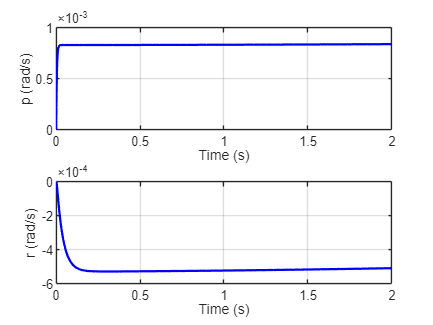


% 2 Extract time and signal data
t = out.r.Time;      % Time vector
r = out.r.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% 2 Extract time and signal data
p = out.p.Data;

% 3 Compute step response characteristics

% Plot for verification
subplot(2,1,1)
plot(t, p, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('p (rad/s)');
grid on;

% Plot for verification
subplot(2,1,2)
plot(t, r, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('r (rad/s)');
grid on;


% Compute step response characteristics
info = stepinfo(p, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0087
    TransientTime: 0.0177
     SettlingTime: 0.0177
      SettlingMin: 7.6071e-04
      SettlingMax: 8.3965e-04
        Overshoot: 0
       Undershoot: 0
             Peak: 8.3965e-04
         PeakTime: 2




% Compute step response characteristics
info = stepinfo(r, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0713
    TransientTime: 1.3283
     SettlingTime: 1.3283
      SettlingMin: -5.2822e-04
      SettlingMax: -4.6522e-04
        Overshoot: 3.8622
       Undershoot: 0
             Peak: 5.2822e-04
         PeakTime: 0.2959

